    %question 1
%Lagrange interpolating
    x=[2;4;6];
    f=[3;5;7];
    u=[2.5;3.5;7.9];%column vector
    
    v=polyinterp(x,f,u)

    3.5000

    4.5000

    8.9000



v =     3.5000         0         0
    4.5000         0         0
    8.9000         0         0


    
    function v=polyinterp(x,f,u)
        %x = [2; 4; 6]; column vector
        %x = [2, 4, 6]; row vector
        row=size(x,1);
        %row=size(x,1); 1 means number of rows
        %row=size(x,2); 2 means numbers of columnn
        
        u_size=size(u,1);
        v = zeros(u_size);
        for k=1:u_size
            px=0;
            for i= 1:row
                Ljx=1;
                for j = 1:row
                    if i~=j
                        Ljx = Ljx * ((u(k)-x(j))/(x(i)-x(j)));
                    end
                end
                px=px+(Ljx*f(i));
            end
            disp(px);
            v(k)=px;
        end
    end

f = @(x) exp(sin(5.5*x));

n = [15 30 60];

x = linspace(-2, 2, n);
fx = f(x);

x_dense = linspace(-2, 2, 1000);
f_true = f(x_dense);

p_val = polyinterp2(x,fx,x_dense)

p_val =     2.7183   -6.4775  -14.8914  -22.5657  -29.5405  -35.8545  -41.5449  -46.6472  -51.1954  -55.2221  -58.7585  -61.8344  -64.4784  -66.7178  -68.5787  -70.0859  -71.2631  -72.1332  -72.7176  -73.0370  -73.1111  -72.9584  -72.5968  -72.0431  -71.3133  -70.4228  -69.3860  -68.2166  -66.9274  -65.5310  -64.0387  -62.4616  -60.8101  -59.0940  -57.3223  -55.5038  -53.6466  -51.7582  -49.8460  -47.9164  -45.9759  -44.0301  -42.0845  -40.1443  -38.2139  -36.2978  -34.3999  -32.5239  -30.6731  -28.8507


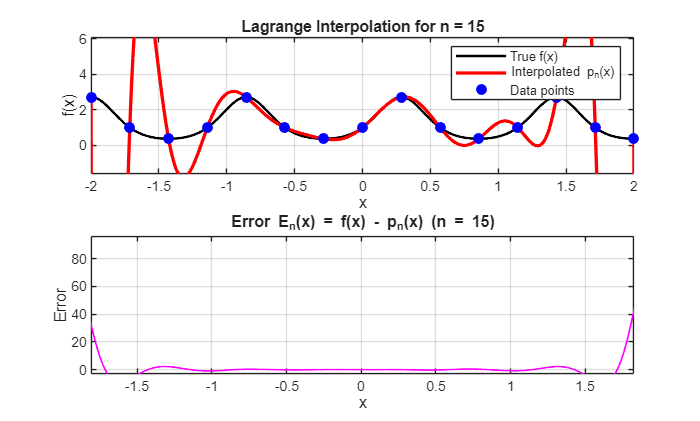

error_val = f_true - p_val;

% ---- Plot f(x) and p_n(x) ----
figure;
subplot(2,1,1);
plot(x_dense, f_true, 'k', 'LineWidth', 1.5); hold on;
plot(x_dense, p_val, 'r', 'LineWidth', 2);
plot(x, fx, 'bo', 'MarkerFaceColor', 'b');
legend('True f(x)', 'Interpolated p_n(x)', 'Data points');
title(['Lagrange Interpolation for n = ', num2str(n)]);
xlabel('x'); ylabel('f(x)');
grid on;

% ---- Plot error ----
subplot(2,1,2);
plot(x_dense, error_val, 'm', 'LineWidth', 1);
title(['Error E_n(x) = f(x) - p_n(x) (n = ', num2str(n), ')']);
xlabel('x'); ylabel('Error');
grid on;

subplot(2,1,1)
xlim([-2.00 2.00])
ylim([0.00 2.98])

function v = polyinterp2(x, f, u)
    n = length(x);              % safer than size(x,1)
    m = length(u);
    v = zeros(size(u));         % preallocate output

    for k = 1:m
        px = 0;
        for i = 1:n
            Ljx = 1;
            for j = 1:n
                if i ~= j
                    Ljx = Ljx * ((u(k) - x(j)) / (x(i) - x(j)));
                end
            end
            px = px + Ljx * f(i);
        end
        v(k)=px;
    end 
end

    %barycentric interpolating
    x=[2;4;6];
    f=[3;5;7];
    u=[2.5;3.5;7.9];
    
    result_wj=barycent(x,f,u);
    disp(result_wj)

    3.5000
    4.5000
    8.9000



    function v=barycent(x,f,u)
        % ensures you consistently get the row dimension, regardless of whether the vector is a row or column vector
        x_len=size(x,1);
        %makes a column vector of length x_len where every entry is 1.
        wj = ones(x_len, 1);
        for i=1:x_len
            for j=1:x_len
                if i~=j
                    wj(i) = wj(i) / ((x(i) - x(j)));
                end
            end
        end
        
        % make a zero vector of same size as u
        v = zeros(size(u));
        u_len=size(u,1);
        
        for k=1:u_len
            % checks if any element of that logical vector is true
            if any(u(k) == x)
                v(k) = f(u(k) == x); 
                continue;
            end
            numerator = 0;
            denominator = 0;
            for i=1:x_len
                term=wj(i) / (u(k) - x(i));
                denominator = denominator + term;
                numerator = numerator + term*f(i); 
            end
            v(k)=numerator/denominator;
        end
    end

    %newton interpolating
    x=[2;4;6];
    f=[3;5;7];
    u=[2.5;3.5;7.9];
    
    [dd, coeffs, val] = newton_dd_eval(x,f,u);
    disp('Divided-difference table (dd):'); disp(dd)

Divided-difference table (dd):
     3     0     0
     5     1     0
     7     1     0



    disp('Values at u:'); disp(val)

Values at u:
    3.5000
    4.5000
    8.9000



    function [dd, coffs, result_array]=newton_dd_eval(x,f,u)
        n=size(x,1);
        dd=zeros(n,n);
        % Take all rows (:) of column 1 and fill them with the vector f.
        dd(:,1) = f;
        for col = 1 : n-1          
            for row = col+1 : n      
                dd(row,col+1) = ( dd(row,col) - dd(row-1,col) ) / ( x(row) - x(row-col) );
            end
        end

        %extracting the diagonal
        coffs=diag(dd);
        number_of_data=length(u);
        result_array=zeros(number_of_data,1);
        for k=1:number_of_data
            value=coffs(n);
            for j=n-1:-1:1
                value=coffs(j)+(u(k)-x(j))*value;
            end
            result_array(k)=value;
        end
    end

figure( position ,get(0,screensize))

position requires one of the following:
  Navigation Toolbox
  Simulink 3D Animation

axes(position ,[0 0 1 1])
[x,y] = ginput;
n = length(x);
s = (1:n) ;
t = (1:.05:n);
u = spline(s,x,t);
v = spline(s,y,t);
clf reset
plot(x,y, '.', u,v, '-' )

%lab 3 %part 4
g = @(x) 1./(1 + 25*x.^2);
xx = linspace(-1,1,1000);

N = [5 10 15 20];
err_poly = zeros(size(N));
err_spline = zeros(size(N));

figure(1);
clf;
for k=1:length(N)
    n=N(k);
    xnodes= linspace(-1,1,n);
    fx=g(xnodes);

    %give equation
    pequa=polyfit(xnodes,fx,n-1);
    p5=polyval(pequa,xx);
    
    err_poly(k) = max(abs(g(xx) - p5));
end

semilogy(N, err_poly,'o-');
plot(xx,p5,'r--','LineWidth',1.5);
grid on;
title('Polynomial interpolation error');


figure(2); clf;
xnodes15 = linspace(-1,1,15);
p15 = polyval(polyfit(xnodes15, g(xnodes15),14), xx);
xnodes20 = linspace(-1,1,20);
p20 = polyval(polyfit(xnodes20, g(xnodes20),19), xx);
plot(xx,g(xx),'k','LineWidth',2); hold on;
plot(xx,p15,'r--','LineWidth',1.5);
plot(xx,p20,'b-.','LineWidth',1.5);
legend('g(x)','p_{15}(x)','p_{20}(x)','Location','Best');
title('Runge function and polynomial interpolants');


figure(3); clf;
for n = [10 15 20]
    xnodes = linspace(-1,1,n);
    pval = polyval(polyfit(xnodes, g(xnodes), n-1), xx);
    plot(xx, abs(g(xx)-pval), 'DisplayName',sprintf('n=%d',n)); hold on;
end
legend show; xlabel('x'); ylabel('|g - p_n|');
title('Pointwise polynomial interpolation error');
grid on;

figure(4); clf;
for k = 1:length(N)
    n = N(k);
    xnodes = linspace(-1,1,n);
    ynodes = g(xnodes);
    sval = spline(xnodes, ynodes, xx);
    err_spline(k) = max(abs(g(xx) - sval));
end
semilogy(N, err_spline,'s-','LineWidth',1.5);
xlabel('n'); ylabel('||g - s_n||_\infty');
title('Spline interpolation error');
grid on;